%The following is the code from last lab
% Q2
folders = dir('Face\training');
folders = folders(~ismember({folders.name}, {'.', '..'}));
subFolders = folders([folders.isdir]);
mat = []


mat =

     []



mean_mat = []


mean_mat =

     []



for K = 1:length(subFolders)
    cur_dr1 = ['Face\training\' subFolders(K).name];
    images = dir(cur_dr1);
    images = images(~ismember({images.name},{'.','..'}));
    for i = 1:length(images)
        img_mat = imread([cur_dr1 '\' images(i).name]);
        img_mat = img_mat(:, :, 1);        %turning the image into a greyside by only cosididering the first channel
        img_mat = reshape(img_mat, [], 1);
        mat = [mat img_mat];
    end
end
mean_mat = mean(mat, 2);
% Making our data X
im2 = reshape(mean_mat, [112, 92])

im2 =    95.7000   95.5594   95.9188   95.7844   96.0094   96.2750   96.1469   95.7469   96.0375   95.9625   95.6875   95.3594   94.6031   94.4656   94.1344   93.6281   93.4594   92.6000   92.3438   92.2188   92.7125   92.9219   91.9813   90.8125   89.5094   88.4781   86.9375   86.2687   84.9437   84.0719   84.1188   83.3500   82.6406   82.0094   82.5187   81.9688   82.6656   83.7000   82.5344   83.1281   82.7750   82.9656   82.9031   81.9313   81.8594   81.1937   80.7938   80.3906   81.9250   81.9250
   95.8063   96.0125   95.7031   95.7625   96.1906   95.9844   95.8250   95.9313   95.6125   95.5438   95.1781   94.7406   93.8156   93.5406   93.2938   92.6156   92.3406   92.3625   91.7281   91.0750   91.0844   91.5062   89.9000   89.2812   87.5469   86.2719   85.2438   84.7281   83.3781   83.5000   83.2094   83.2000   82.2219   83.1063   83.4688   83.4719   83.8219   85.4281   84.7156   84.0187   84.1562   84.4313   83.9406   83.2750   83.1719   82.9156   82.3125   82.1125   81.7500   

im3 = cast(im2, "uint8")

im3 = 112×92 uint8 matrix
    96    96    96    96    96    96    96    96    96    96    96    95    95    94    94    94    93    93    92    92    93    93    92    91    90    88    87    86    85    84    84    83    83    82    83    82    83    84    83    83    83    83    83    82    82    81    81    80    82    82
    96    96    96    96    96    96    96    96    96    96    95    95    94    94    93    93    92    92    92    91    91    92    90    89    88    86    85    85    83    84    83    83    82    83    83    83    84    85    85    84    84    84    84    83    83    83    82    82    82    81
    96    96    96    96    96    96    96    96    95    95    94    94    93    92    92    92    92    91    90    90    90    89    88    87    85    85    85    84    84    84    85    85    85    85    85    84    85    86    86    86    86    86    86    85    85    85    85    84    83    83
    96    96    96    96    95    96    96    95    95    94    93    9

lol = size(im3)

lol =    112    92


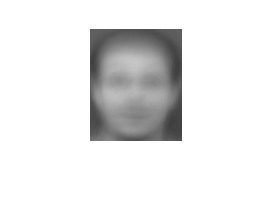

imshow(im3)

imwrite(im3, "mean.bmp")
%Subtract the mean image from all the samples
data_X = []


data_X =

     []



for K = 1:320
    %temp = reshape(mat(:, K), [112, 92]);
    subs = cast(mat(:, K), "double") - mean_mat;
    d_subs = size(subs);
    
    data_X = [data_X subs];
end
%2.5
size(data_X)

ans =        10304         320


trans_data_X = data_X'

trans_data_X =   -53.7000  -56.8063  -56.9813  -52.8031  -56.0344  -55.7719  -56.7562  -55.7500  -53.8844  -48.0687  -48.6594  -50.9656  -46.7969  -46.5312  -42.7500  -52.3969  -48.8375  -46.8625  -45.2562  -40.5000  -39.2656  -28.0281  -29.0656  -18.6750  -25.3812  -24.3312  -20.0812  -30.7375  -28.3688  -30.6781  -40.3937  -35.2344  -20.0094  -12.8750   -4.1750   -2.9156  -12.8875  -18.4250  -30.5563  -31.2906  -28.9813  -26.7125  -33.5594  -34.1437  -31.5750  -35.5187  -36.5094  -37.1781  -38.0375   29.3312
  -28.7000  -31.8063  -19.9813   -6.8031  -42.0344  -48.7719  -39.7562  -39.7500  -33.8844  -15.0687  -19.6594   -8.9656  -13.7969  -17.5312  -17.7500   -8.3969  -12.8375    0.1375  -13.2562    0.5000   -2.2656   10.9719  -14.0656    9.3250   23.6188   24.6688   15.9188   19.2625   19.6312   25.3219   26.6063   18.7656   26.9906   16.1250   16.8250   25.0844   28.1125   26.5750   40.4437   17.7094   18.0187   19.2875   27.4406   26.8563   32.4250   50.4813   71.4906   85.8219   8

T = (trans_data_X*data_X)/320

T = 1.0e+05 *

    0.5031    0.1547    0.2974    0.2162    0.1959    0.2086    0.3750    0.3756   -0.0155    0.0548    0.0536    0.0347    0.1403    0.0711    0.0864    0.1170    0.0056   -0.0032    0.0538    0.1201    0.1016   -0.0087   -0.0008   -0.0110    0.2229    0.0604    0.0287    0.0267    0.0563    0.1437    0.0421    0.1268   -0.0244   -0.0317    0.0434    0.0309    0.0252   -0.0055    0.0306    0.0447   -0.0826   -0.0766   -0.0886   -0.0816   -0.1320   -0.0132   -0.0293   -0.0083    0.0336   -0.1559
    0.1547    1.1627    0.3802    0.5555    0.8248    0.4856    0.5670    0.3822   -0.3000   -0.2973   -0.2315   -0.1452   -0.0930   -0.1324   -0.2268   -0.2212   -0.3191   -0.3000   -0.2254   -0.0897   -0.1422   -0.3295   -0.3033   -0.2030    0.3554    0.1635    0.1802    0.1199    0.1517    0.2639    0.1110    0.3808    0.2084    0.2740    0.6031    0.5037    0.1905    0.2848    0.2697    0.3032    0.0209    0.0413   -0.0097   -0.0534   -0.0010   -0.1797   -0.1889   -0.1224    

size(T)

ans =    320   320



[U, D, V] = svd(data_X)

U =     0.0069    0.0165    0.0177    0.0039    0.0065   -0.0063   -0.0080    0.0072   -0.0017    0.0018    0.0063    0.0078    0.0081   -0.0089    0.0004    0.0025    0.0007    0.0038   -0.0015    0.0091   -0.0112    0.0102   -0.0019    0.0036   -0.0100   -0.0073   -0.0044    0.0039   -0.0076    0.0025   -0.0069   -0.0029    0.0038    0.0059   -0.0037    0.0020    0.0021   -0.0152   -0.0011   -0.0010    0.0089   -0.0027    0.0001   -0.0008   -0.0075    0.0061   -0.0026   -0.0109   -0.0071    0.0035
    0.0069    0.0165    0.0180    0.0038    0.0066   -0.0061   -0.0077    0.0071   -0.0018    0.0020    0.0059    0.0077    0.0072   -0.0093    0.0013    0.0028    0.0001    0.0028   -0.0009    0.0089   -0.0101    0.0104   -0.0015    0.0038   -0.0102   -0.0072   -0.0048    0.0031   -0.0080    0.0023   -0.0073   -0.0033    0.0040    0.0066   -0.0038    0.0023    0.0022   -0.0136   -0.0005   -0.0020    0.0088   -0.0021   -0.0007   -0.0006   -0.0066    0.0059   -0.0033   -0.0098   -0.0066    0

D = 1.0e+04 *

    3.7732         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    3.3213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

V =     0.0243    0.0016   -0.1103    0.0139   -0.0310    0.0014   -0.0304    0.0028   -0.0265    0.1214    0.0032   -0.0486    0.0495   -0.0253    0.0143   -0.0683    0.0075   -0.0740    0.0182   -0.0307    0.0264   -0.0164    0.0804   -0.0335    0.0201    0.0216    0.0440   -0.0001    0.0699   -0.0274    0.0634   -0.0061    0.0354   -0.0424    0.0019   -0.0551    0.0437   -0.0627    0.0651   -0.0022    0.0433   -0.1038    0.0102   -0.0272    0.0085   -0.0208    0.0327    0.0005    0.0189   -0.0826
    0.0944   -0.0140    0.0101   -0.0008   -0.1857    0.0319    0.0072    0.1199   -0.0551    0.0073    0.0204   -0.0128   -0.0038    0.1378    0.0301    0.0192   -0.0175   -0.0220   -0.1166   -0.1058   -0.0593   -0.0607    0.0023   -0.0784    0.0674    0.0297    0.0153   -0.0934   -0.0552    0.0212   -0.0670   -0.1030   -0.0209   -0.0227   -0.0428   -0.1216    0.0351    0.0027   -0.0690    0.0085    0.0906   -0.0438    0.0034   -0.0229    0.0085    0.0288    0.0838    0.0969    0.0777   -0

eig_faces_SVD = U

eig_faces_SVD =     0.0069    0.0165    0.0177    0.0039    0.0065   -0.0063   -0.0080    0.0072   -0.0017    0.0018    0.0063    0.0078    0.0081   -0.0089    0.0004    0.0025    0.0007    0.0038   -0.0015    0.0091   -0.0112    0.0102   -0.0019    0.0036   -0.0100   -0.0073   -0.0044    0.0039   -0.0076    0.0025   -0.0069   -0.0029    0.0038    0.0059   -0.0037    0.0020    0.0021   -0.0152   -0.0011   -0.0010    0.0089   -0.0027    0.0001   -0.0008   -0.0075    0.0061   -0.0026   -0.0109   -0.0071    0.0035
    0.0069    0.0165    0.0180    0.0038    0.0066   -0.0061   -0.0077    0.0071   -0.0018    0.0020    0.0059    0.0077    0.0072   -0.0093    0.0013    0.0028    0.0001    0.0028   -0.0009    0.0089   -0.0101    0.0104   -0.0015    0.0038   -0.0102   -0.0072   -0.0048    0.0031   -0.0080    0.0023   -0.0073   -0.0033    0.0040    0.0066   -0.0038    0.0023    0.0022   -0.0136   -0.0005   -0.0020    0.0088   -0.0021   -0.0007   -0.0006   -0.0066    0.0059   -0.0033   -0.0098   

eig_val_SVD = (diag(D).^2)/320

eig_val_SVD = 1.0e+06 *

    4.4491
    3.4471
    1.5136
    1.2750
    1.0001
    0.8051
    0.5892
    0.5445
    0.4772
    0.4113


eig_6_max_vec_SVD = []


eig_6_max_vec_SVD =

     []



[eig_val_SVD_sorted, eig_val_indices] = sort(eig_val_SVD, 'descend');


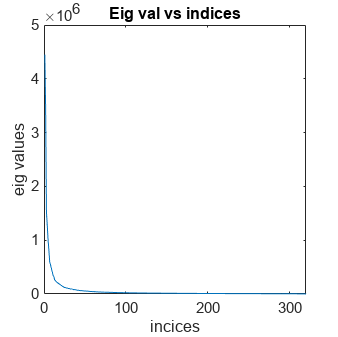

% Part 2
%Q1 We need to plot the eigenvalues vs the index
plot(eig_val_indices, eig_val_SVD_sorted)
ylabel("eig values")
xlabel("incices")
title("Eig val vs indices")
%set(gcf,'Position',[100 100 500 500])
% Now the question remains that how do we choose the right value for K
% We will choose the point on the curve where the eigenvalues start to
% level off. Looking at out curve, I identified that the appropriate value
% for K should be 22
set(gcf,'Position',[100 100 500 500])

% Part 3
%Reconstruction using 100 eigenfaces
% Looking at the curve I figured that the eigenvalue saturaates at around
% the 100 mark and thus the eigenvectors beyond that point don't contain a
% lot of value beyond that point (ofcourse we can also try to reduce this
% value if we are looking at the computational/time trade-off. 
eig_seventy_face = U(:, 1:40);
eig_seventy_face_t = eig_seventy_face'

eig_seventy_face_t =     0.0069    0.0069    0.0069    0.0069    0.0066    0.0065    0.0066    0.0066    0.0067    0.0067    0.0067    0.0069    0.0069    0.0075    0.0078    0.0078    0.0080    0.0083    0.0087    0.0090    0.0094    0.0091    0.0087    0.0081    0.0077    0.0072    0.0070    0.0069    0.0072    0.0068    0.0069    0.0070    0.0071    0.0072    0.0070    0.0069    0.0070    0.0072    0.0071    0.0076    0.0079    0.0080    0.0074    0.0065    0.0057    0.0053    0.0056    0.0065    0.0063    0.0062
    0.0165    0.0165    0.0164    0.0164    0.0164    0.0162    0.0161    0.0162    0.0160    0.0158    0.0155    0.0146    0.0142    0.0138    0.0135    0.0130    0.0128    0.0123    0.0119    0.0116    0.0109    0.0101    0.0093    0.0087    0.0075    0.0064    0.0050    0.0037    0.0028    0.0021    0.0024    0.0027    0.0031    0.0033    0.0027    0.0022    0.0015    0.0011    0.0014    0.0014    0.0017    0.0024    0.0020    0.0013    0.0007    0.0001   -0.0000    0.00

W_mat = []


W_mat =

     []



for K = 1:length(subFolders)
    cur_dr1 = ['Face\training\' subFolders(K).name];
    images = dir(cur_dr1);
    images = images(~ismember({images.name},{'.','..'}));
    for i = 1:length(images)
        img_mat1 = imread([cur_dr1 '\' images(i).name]);
        img_mat1 = img_mat1(:, :, 1);        %turning the image into a greyside by only cosididering the first channel
        img_mat1 = reshape(img_mat1, [], 1);
        img_mat1 = cast(img_mat1, "double");
        W = eig_seventy_face_t*(img_mat1-mean_mat);
        W_mat = [W_mat W];
    end
end

size(W_mat)

ans =     40   320


W_mean = mean(W_mat, 2)

W_mean = 1.0e-12 *

    0.8029
   -0.5912
    0.3165
    0.0448
   -0.4995
    0.2075
    0.3235
   -0.0043
    0.1164
   -0.1265


arctic = imread("arctichare.png");
arctic = arctic(:, :, 1)   %Turning the image into a greyscale image

arctic = 400×594 uint8 matrix
   146   151   142   133    98    90    97   124   129   136   153   161   179   207   215   216   213   210   213   219   221   216   209   185   163   136   114   103   106   121   119    98    88    79    84   101   124   149   172   173   157   137   118    96    98   105   105    98    93    78
   147   147   139   126   103    97   104   122   134   141   153   161   177   201   210   212   208   201   201   209   216   219   210   177   148   113    90    92   110   125   122   105    92    88    92   108   128   155   172   170   153   130   106    96    96    97    96    95    92    78
   144   142   134   126   108   104   113   122   135   136   154   170   192   205   206   199   190   180   178   187   210   214   187   156   121    82    71    86   105   124   125   118   103    98   108   118   129   143   147   148   129   108    92    88    88    88    88    92    96    91
   142   139   133   115   113   117   122   127   132   137   158 

arctic = imresize(arctic, [112, 92]);
arctic = reshape(arctic, [], 1);
arctic = cast(arctic, "double");
W_arctic = eig_seventy_face_t*(arctic-mean_mat);

% Eucledian distance between W_arctic and W_mean
eud_dis_arctic = norm(W_arctic- W_mean)

eud_dis_arctic = 9.7603e+03

rand_img = imread("Face\testing\s5\9.png")

rand_img = 112×92×3 uint8 array
rand_img(:,:,1) =

   149   151   149   155   149   147   151   149   152   151   153   151   151   147   153   149   147   149   144   151   151   159   146   140   143   129   128   144   143   138   140   156   147   163   160   153   165   152   149   144   133   103   113   102    97    91    81    89    89    73    89   112   107   102   107   126   131   131   140   149   144   137   134   142   151   146   147   146   147   151   149   147   151   152   153   147   149   149   147   147   149   149   147   152   151   147   152   147   149   147   149   147
   149   153   149   152   152   149   152   152   152   152   151   152   152   149   151   151   140   153   147   147   147   155   142   134   133   131   142   151   151   138   139   159   153   165   170   151   161   159   159   155   135   118   120   109   115   103   103    80    91    93   107    73    85   102   135   131   135   133   131   140   143   139   142   131   138   128

rand_img = rand_img(:, :, 1);
rand_img = reshape(rand_img, [], 1);
rand_img = cast(rand_img, "double");
W_test = eig_seventy_face_t*(rand_img - mean_mat);
eud_dist_test = norm(W_test - W_mean)

eud_dist_test = 4.2596e+03

% Comparing the above eucledian distances, we can clearly see that the
% eucledian distnce dtest is lower than the eucledian distance darctichare

%Question 3
%The for loop below takes four images form the testing dataset and
%then finds the W_test and the respective eucledian distance for all of the
%images
k = 1;
euc_dist = [];
W_test_i = cell(1, 4);
j = 9;
for i = 2:5
    name_of_file = sprintf("Face\\testing\\s%d\\%d.png", i, j);
    r_i = imread(name_of_file);
    r_i = r_i(:, :, 1);
    r_i = reshape(r_i, [], 1);
    r_i = cast(r_i, "double");
    W_test_s = eig_seventy_face_t*(r_i - mean_mat);
    W_test_i{k} = W_test_s;
    euc_dics = norm(W_test_s - W_mean);
    euc_dist = [euc_dist euc_dics];
    k = k+1;
end
%The following line display all the Wtest for the four images 
W_test_1 = W_test_i{1}  

W_test_1 = 1.0e+03 *

   -0.5279
   -2.0149
   -0.9434
    1.2157
   -0.2077
   -0.1586
    0.9792
    0.6684
   -0.5768
    0.4238


W_test_2 = W_test_i{2}

W_test_2 = 1.0e+03 *

    1.8508
    1.5657
   -0.6818
   -1.0966
    1.4388
    0.5562
   -0.4443
    0.2906
   -0.0670
   -0.1594


W_test_3 = W_test_i{3}

W_test_3 = 1.0e+03 *

   -0.4913
    0.5598
   -0.1042
   -0.0814
    1.3806
    1.8073
    0.1425
    0.5596
   -0.7164
    0.1399


W_test_4 = W_test_i{4}

W_test_4 = 1.0e+03 *

    3.1191
    1.7757
    0.7065
   -0.5395
   -0.9448
   -0.0845
    0.5547
   -0.5611
    0.7714
    0.7408


disp(euc_dist)         %This line displays all the eucledian distancesfor the 

   1.0e+03 *

    3.4300    3.6500    3.1578    4.2596



                       % four Weights as an array


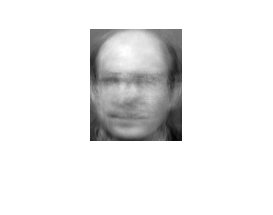

% % Question 4
% We need to calculate the mean weights for each and every person in the
% dataset
% We had stored the all the weights of each image in the matrix called
% W_mat, so now all we need to do is to access all that data in multiples
% of 9 and the find the mean and we can easily achieve this using a nested
% loop
W_p_mean_tot = [];
 for i = 1:length(subFolders)
     W_i_tot = [];
     W_p_mean = [];
     recost_W_p = [];
     reconstructed_W_p = [];
     for j = 8*(i-1)+1:8*(i-1)+8 
         W_i = W_mat(:, j);
         W_i_tot = [W_i_tot W_i];
     end
     W_p_mean = mean(W_i_tot, 2);  % reconstruct this
     recost_W_p = (eig_seventy_face * W_p_mean) + mean_mat;
     reconstructed_W_p = reshape(recost_W_p, [112, 92]);
     reconstructed_W_p = (reconstructed_W_p - min(reconstructed_W_p, [], 'all')) / (max(reconstructed_W_p, [], 'all') - min(reconstructed_W_p, [], 'all'));
     
     if i<=5 
         imshow(reconstructed_W_p)
         imwrite(reconstructed_W_p, sprintf("test_%d.bmp", i))
     end
%      imwrite(reconstructed_mat_img, sprintf("Q8rec.bmp"))
%      plot_img = imresize(W_p_mean, [112, 92]);
%      plot_img = cast(plot_img, "double");
%      imshow(plot_img)
      W_p_mean_tot = [W_p_mean_tot W_p_mean];    %This matrix contains the mean Weight matrix for each person
      
 end

% Question 5
% Loading the test dataset
% I am using tic/tac to measure the time it takes to run on our testing
% dataset
folders_t = dir('Face\testing');
folders_t = folders_t(~ismember({folders_t.name}, {'.', '..'}));
subFolders_t = folders_t([folders_t.isdir]);
test_mat = [];
W_test_tot = [];
actual = [];
euc_dist_Q5_tot = [];
for K = 1:length(subFolders)
    cur_dr1 = ['Face\testing\' subFolders(K).name];
    images = dir(cur_dr1);
    images = images(~ismember({images.name},{'.','..'}));
    for i = 1:length(images)
        actual = [actual K];
        img_mat2 = imread([cur_dr1 '\' images(i).name]);
        img_mat2 = img_mat2(:, :, 1);        %turning the image into a greyside by only cosididering the first channel
        img_mat2 = reshape(img_mat2, [], 1);
        img_mat2 = cast(img_mat2, "double");
        test_mat = [test_mat img_mat2];
        W_test = eig_seventy_face_t*(img_mat2 - mean_mat);
        W_test_tot = [W_test_tot W_test];
    end
end
% Now since we have found the eucledian distances for all the images we need
% to index with the min eucledian distance foa lll 80 images and then we
% can calculate the accuracy of our model
tic
min_preds_index = [];
min_preds_euc = [];
for l = 1:80
    euc_dist_Q5_tot = [];
    for g = 1:40
        euc_dist_Q5 = norm(W_test_tot(:, l) - W_p_mean_tot(:, g));
        euc_dist_Q5_tot = [euc_dist_Q5_tot euc_dist_Q5];
    end
    [min_euc_dist, index_eud_dist] = mink(euc_dist_Q5_tot, 1);
    min_preds_index = [min_preds_index index_eud_dist];
    min_preds_euc = [min_preds_euc min_euc_dist];
end
% The above code gives us both the index and the minimum eucledian distance
% for all the values. Now we can calculate the accuracy of our model
acc_Q5 = sum(min_preds_index == actual)/80; % this is the accuracy for Q5
toc

Elapsed time is 0.032827 seconds.


str = sprintf("Accuracy of model in Q5 is %0.4f", acc_Q5);
disp(str)

Accuracy of model in Q5 is 0.8875


% Question 6
% In this part of the lab we shall use KNN to find the label of each test
% image.
% In part three of this lab we had made a weight vector for all the test
% images names Wmat
% Now we need to calculate the eucledian distance of the weight vector of
% every test sample from the weight wevtor of every image and the choose
% and then do the majority voting
tic
K = 5; %Note K here represents the K shortest distances we are considering 
knn_preds = [];
for a = 1:80
    euc_dist_Q6_tot = [];
    for b = 1:320
        euc_dist_Q6 = norm(W_mat(:, b) - W_test_tot(:, a));
        euc_dist_Q6_tot = [euc_dist_Q6_tot euc_dist_Q6];
    end
    [K_min_euc_dist_Q6, index_k_min_Q6] = mink(euc_dist_Q6_tot, K);
    most_freq = mode(ceil(index_k_min_Q6/8));  
    % Calculating the index of the person
    %in the above statement I am calculating the mode because I want to
    %know which element has the most frequency. I alst divide the index by
    %8 and the round it to the next integer to get the correct index
    knn_preds = [knn_preds most_freq];
end
acc_knn = sum(knn_preds == actual)/80;
str_Q6 = sprintf("The accuracy of KNN model is %0.4f", acc_knn);
disp(str_Q6)

The accuracy of KNN model is 0.9250


toc

Elapsed time is 0.374236 seconds.


%Q7 In this section of the lab I'm trying to test to see what subject does my
%face match to the most
K = 5;
my_img = imread("Abhi_Sharma_face1.jpg");
my_img_lin = reshape(my_img, [], 1);
my_img_lin = cast(my_img_lin, "double");
W_my_face = eig_seventy_face_t*(my_img_lin - mean_mat);
euc_dist_my_face_tot = [];
for p = 1:320
    euc_dist_my_face = norm(W_my_face - W_mat(:, p));
    euc_dist_my_face_tot = [euc_dist_my_face_tot euc_dist_my_face];
end
[K_min_euc_dist_Q7, index_k_min_Q7] = mink(euc_dist_my_face_tot, K);
pred_my_face = mode(ceil(index_k_min_Q7/8));
disp("My face was predicted as subject s22");

My face was predicted as subject s22
